clear;

## Q2

**Eigenvalues**

ew = cell(1, 3);
N = [10 100 1000];

for i = 1:3
    n = N(i);
    col = [-2 1 zeros(1, n-2)];
    A = 1/n*toeplitz(col);
    ew{i} = eig(A);
    % eig(inv(A));
end

T = tiledlayout(1,1);
T.Units = 'inches';
T.OuterPosition = [0 0 4 4];

% preamble
f1q2 = nexttile();
legend('location', 'northeast');
xlabel("Re(z)");
ylabel("Im(z)");
axis([-0.4 0 -1 1])
formatSpec = (" (N = %d)");
C = hsv(3);

% plot
hold on;
for i = 1 : 3
    x = ew{i};
    y = zeros(1, N(i));
    str23 = sprintf(formatSpec, N(i));
    plot(x, y, '.', 'MarkerSize', 10, 'Color', C(i, :), ...
        'DisplayName', strcat('\lambda', str23));
end
hold off;

exportgraphics(f1q2, [pwd '/Figures/HW2_q2_spectrum.png']);

**Stability Regions**

T = tiledlayout(1,1);
T.Units = 'inches';
T.OuterPosition = [0 0 4 4];

% preamble
f2q2 = nexttile();
legend('location', 'northeast');
xlabel("Re(z)");
ylabel("Im(z)");
axis([-2 2 -2 2])
formatSpec = (" (N = %d)");
C = hsv(3);

% forward euler region
t = linspace(0, 2*pi, 250);
xFE = cos(t)-1;
yFE = sin(t);
% backward euler region
xBE = [-2 2 2 -2];
yBE = [-2 -2 2 2];
% trapezoidal rule region
trapx = [0 0 -2 -2];
trapy = [-2 2 2 -2];

hold on;
% foward euler
patch(xFE, yFE, "blue", 'LineStyle', 'none', 'FaceAlpha', 0.25, ...
    'DisplayName', "Foward Euler");
plot(xFE, yFE, 'Color', "blue", 'LineStyle', '-', 'LineWidth', 1.25, ...
    'HandleVisibility', 'off');

% backward euler
patch(xBE, yBE, "red", 'LineStyle', 'none', 'FaceAlpha', 0.25, ...
    'DisplayName', "Backward Euler");
patch(xFE+2, yFE, "white", 'LineStyle', 'none', 'FaceAlpha', 1, ...
    'HandleVisibility', 'off');
plot(xFE+2, yFE, 'Color', "#cf5959", 'LineStyle', '-', 'LineWidth', 1.25, ...
    'HandleVisibility', 'off');

% trapezoidal
patch(trapx, trapy, "green", 'LineStyle', 'none', 'FaceAlpha', 0.25, ...
    'DisplayName', "Trapezoidal Rule");
xline(0, 'Color', "#77AC30", 'LineStyle', ':', 'LineWidth', 2, ...
    'HandleVisibility', 'off');

% eigenvalues
for i = 1 : 3
    x = ew{i};
    y = zeros(1, N(i));
    str23 = sprintf(formatSpec, N(i));
    plot(x, y, '.', 'MarkerSize', 10, 'Color', C(i, :), ...
        'DisplayName', strcat('\lambda', str23));
end
hold off;
exportgraphics(f2q2, [pwd '/Figures/HW2_q2_regions.png']);

**Solving ODE**

tspan = [0 10];
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-6);

N = 3000;
% N = 5000;
% N = 6000;
y0 = sin(2*pi^2/(N+1) * (1:N))';
% y0 = sin(2*pi^2/(N+1) * (1:N))' + rand(N,1);

c = [-2 1 zeros(1, N-2)];
A = 1/N*toeplitz(c);

crap = @(t,y) A*y;
sol23  =  ode23(@(t,y) crap(t,y), tspan, y0, options);
% sol23.stats
% sol23s = ode23s(@(t,y) crap(t,y), tspan, y0, options);
% sol45 = ode45(@(t,y) crap(t,y), tspan, y0, options);
% sol45.stats

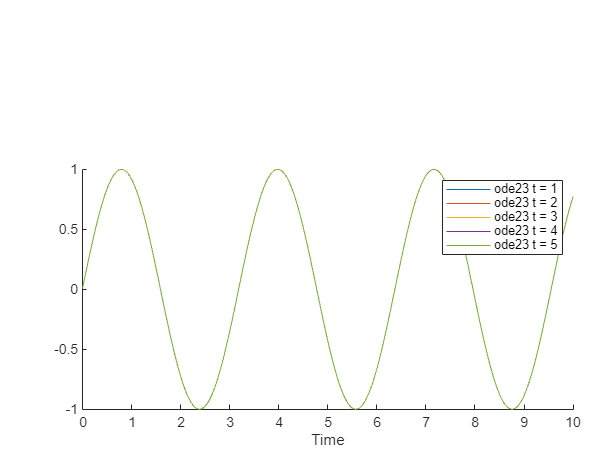

T = tiledlayout(1,1);
T.Units = 'inches';
T.OuterPosition = [0 0 6 3];

% preamble
f2q2 = nexttile();
legend('location', 'northeast');
xlabel("Time");
x = linspace(0, 10, N);
formatSpec23 = "ode23 t = %d";
formatSpec45 = "ode45 t = %d";

hold on;
for i = 1:5
    str23 = sprintf(formatSpec23, i);
    plot(x', sol23.y(:,i), 'DisplayName', str23);
    % plot(x', sol23s.y(:,i));
    % str45 = sprintf(formatSpec45, i);
    % plot(x', sol45.y(:,i), 'DisplayName', str45);
end
hold off;
exportgraphics(f2q2, [pwd '/Figures/HW2_q2_sol_3000.png']);

% exportgraphics(f2q2, [pwd '/Figures/HW2_q2_sol_5000.png']);